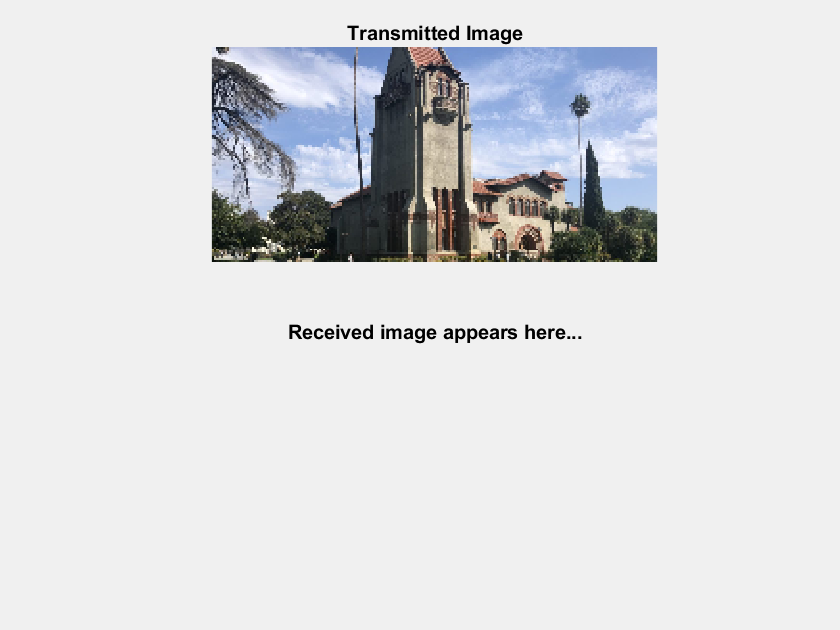

%ref: https://www.mathworks.com/help/wlan/ug/image-transmission-reception-using-802-11-waveform-sdr.html?searchHighlight=image%20transmission&s_tid=srchtitle_support_results_3_image%20transmission
%needs to install WLAN Toolbox

% Setup handle for image plot
if ~exist('imFig','var') || ~ishandle(imFig) %#ok<SUSENS> 
    imFig = figure;
    imFig.NumberTitle = 'off';
    imFig.Name = 'Image Plot';
    imFig.Visible = 'off';
else
    clf(imFig); % Clear figure
    imFig.Visible = 'off';
end

% Setup Spectrum viewer
spectrumScope = spectrumAnalyzer( ...
    SpectrumType='power-density', ...
    Title='Received Baseband WLAN Signal Spectrum', ...
    YLabel='Power spectral density', ...
    Position=[69 376 800 450]);

% Setup the constellation diagram viewer for equalized WLAN symbols
refQAM = wlanReferenceSymbols('64QAM');
constellation = comm.ConstellationDiagram(...
    Title='Equalized WLAN Symbols',...
    ShowReferenceConstellation=true,...
    ReferenceConstellation=refQAM,...
    Position=[878 376 460 460]);

% Input an image file and convert to binary stream
fileTx = 'sjsu.jpg';                   % Image file name
fData = imread(fileTx);                          % Read image data from file
scale = 0.2;                    % Image scaling factor
origSize = size(fData);                          % Original input image size
scaledSize = max(floor(scale.*origSize(1:2)),1); % Calculate new image size
heightIx = min(round(((1:scaledSize(1))-0.5)./scale+0.5),origSize(1));
widthIx = min(round(((1:scaledSize(2))-0.5)./scale+0.5),origSize(2));
fData = fData(heightIx,widthIx,:);               % Resize image
imsize = size(fData); %112,232,3                           % Store new image size
txImage = fData(:); %77952*1 uint8

% Plot transmit image
imFig.Visible = 'on';
subplot(211);
imshow(fData);
title('Transmitted Image');
subplot(212);
title('Received image appears here...');
set(gca,'Visible','off');
set(findall(gca, 'type', 'text'), 'visible', 'on');


%Split the data stream (txImage) into smaller transmit units (MSDUs) of size msduLength. Then, create an MPDU for each transmit unit using the wlanMACFrame function.
msduLength = 2304; % MSDU length in bytes
numMSDUs = ceil(length(txImage)/msduLength);
padZeros = msduLength-mod(length(txImage),msduLength);
txData = [txImage;zeros(padZeros,1)];
txDataBits = double(int2bit(txData,8,false));

% Divide input data stream into fragments
bitsPerOctet = 8;
data = zeros(0,1);

for i=0:numMSDUs-1

    % Extract image data (in octets) for each MPDU
    frameBody = txData(i*msduLength+1:msduLength*(i+1),:);

    % Create MAC frame configuration object and configure sequence number
    cfgMAC = wlanMACFrameConfig(FrameType='Data',SequenceNumber=i);

    % Generate MPDU
    [psdu, lengthMPDU]= wlanMACFrame(frameBody,cfgMAC,OutputFormat='bits');

    % Concatenate PSDUs for waveform generation
    data = [data; psdu]; %#ok<AGROW>

end

%Generate 802.11a Baseband WLAN Signal
nonHTcfg = wlanNonHTConfig;       % Create packet configuration
nonHTcfg.MCS = 6;                 % Modulation: 64QAM Rate: 2/3
nonHTcfg.NumTransmitAntennas = 1; % Number of transmit antenna
chanBW = nonHTcfg.ChannelBandwidth;
nonHTcfg.PSDULength = lengthMPDU; % Set the PSDU length

%Initialize the scrambler with a random integer for each packet.
scramblerInitialization = randi([1 127],numMSDUs,1);

%Set the oversampling factor to 1.5 to generate the waveform at 30 MHz for transmission.
osf = 1.5;

sampleRate = wlanSampleRate(nonHTcfg); % Nominal sample rate in Hz

% Generate baseband NonHT packets separated by idle time
txWaveform = wlanWaveformGenerator(data,nonHTcfg, ...
    NumPackets=numMSDUs,IdleTime=20e-6, ...
    ScramblerInitialization=scramblerInitialization,...
    OversamplingFactor=osf);


## Transmitter Setup

channel = "OverTheAir" %"GaussianNoise";

channel = "OverTheAir"

if strcmpi(channel,"OverTheAir")
    deviceName = "Pluto";
    channelNumber = 5;
    frequencyBand = 2.4;
    txGain = -10;
    rxGain = 10;
elseif strcmpi(channel,"GaussianNoise")
    % Specify SNR of received signal for a simulated channel 
    SNR = 20;
end

%Configure SDR for Transmission
if strcmpi(channel,"OverTheAir")

    % Transmitter properties
    sdrTransmitter = sdrtx(deviceName,'RadioID','ip:192.168.1.10');
    sdrTransmitter.BasebandSampleRate = sampleRate*osf;
    sdrTransmitter.CenterFrequency = wlanChannelFrequency(channelNumber,frequencyBand);
    sdrTransmitter.Gain = txGain;
    
    % Pass the SDR I/O directly to host skipping FPGA on Zynq Radio or USRP
    % Embedded Series Radio
    if ~strcmpi(deviceName,"Pluto")
        sdrTransmitter.ShowAdvancedProperties = true;
        sdrTransmitter.BypassUserLogic = true;
    end

    fprintf('\nGenerating WLAN transmit waveform:\n')

    % Scale the normalized signal to avoid saturation of RF stages
    powerScaleFactor = 0.8;
    txWaveform = txWaveform.*(1/max(abs(txWaveform))*powerScaleFactor);

    % Transmit RF waveform
    transmitRepeat(sdrTransmitter,txWaveform);
end


Generating WLAN transmit waveform:


## Establishing connection to hardware. This process can take several seconds.


## Waveform transmission has started successfully and will repeat indefinitely. 
## Call the release method to stop the transmission.


## Receiver Setup

if strcmpi(channel,"OverTheAir")

    sdrReceiver = sdrrx(deviceName,'RadioID','ip:192.168.1.10'); %sdrrx(deviceName);
    sdrReceiver.BasebandSampleRate = sdrTransmitter.BasebandSampleRate;
    sdrReceiver.CenterFrequency = sdrTransmitter.CenterFrequency;
    sdrReceiver.OutputDataType = 'double';
    sdrReceiver.GainSource = 'Manual';
    sdrReceiver.Gain = rxGain;

    if ~strcmpi(deviceName,"Pluto")
        sdrReceiver.ShowAdvancedProperties = true;
        sdrReceiver.BypassUserLogic = true;
    end

    % Configure the capture length equivalent to twice the length of the
    % transmitted signal, this is to ensure that PSDUs are received in order.
    % On reception the duplicate MAC fragments are removed.
    sdrReceiver.SamplesPerFrame = 2*length(txWaveform);
    fprintf('\nStarting a new RF capture.\n')

    rxWaveform = capture(sdrReceiver,sdrReceiver.SamplesPerFrame,'Samples');
elseif strcmpi(channel,"GaussianNoise")
    rxWaveform = awgn(txWaveform,SNR,'measured');
else % No Impairments
    rxWaveform = txWaveform;
end


Starting a new RF capture.


## Establishing connection to hardware. This process can take several seconds.


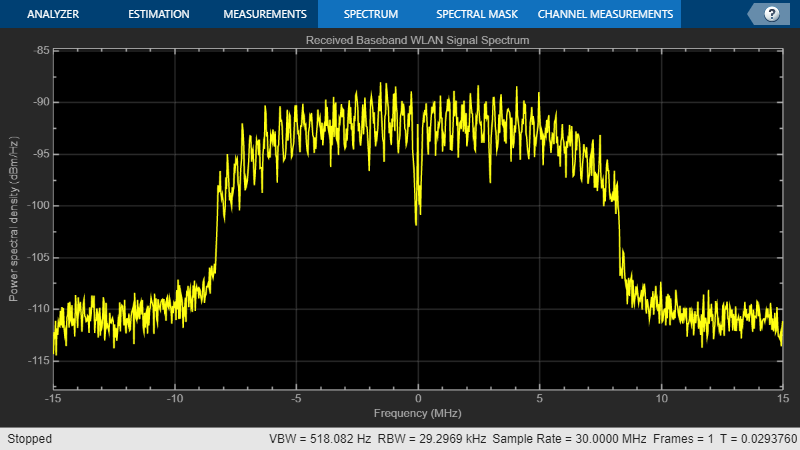


%Show the power spectral density of the received waveform.
spectrumScope.SampleRate = sampleRate*osf;
spectrumScope(rxWaveform);
release(spectrumScope);